## Plot data recorded with gyroscope while turning the camera by hand

The arduino sketch prints 

- the time in milliseconds, 

- the angle phi in degrees,

- the angular velocity omega in degrees per second,

- the signal returned by the sensor (before conversion to degrees per second, before offset compensation). 

The next code block reads this data, extracts t and phi, and plots phi as a function of t. 

close all; 
clear all;
filename_step_response_data= "../arduino/record_gyroscope_data_for_matlab/data_for_matlab.txt";
step_response_data= readtable(filename_step_response_data);

tdata= step_response_data{:, 1}; 
tdata= tdata- tdata(1); % subtract t0
tdata= tdata/1e6; % turn milliseconds into seconds
phidata= step_response_data{:,2};

plot(tdata, phidata);

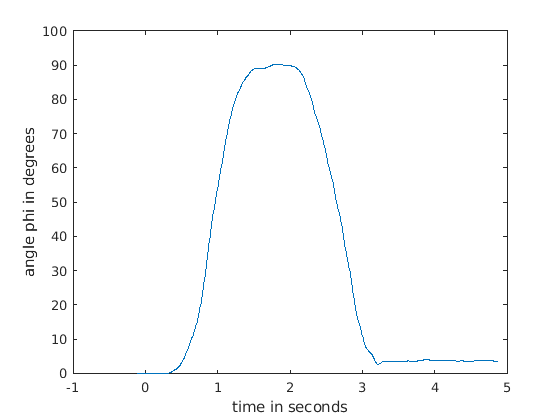

ylabel("angle phi in degrees"); 
xlabel("time in seconds"); 

Plot the gyrometer data.

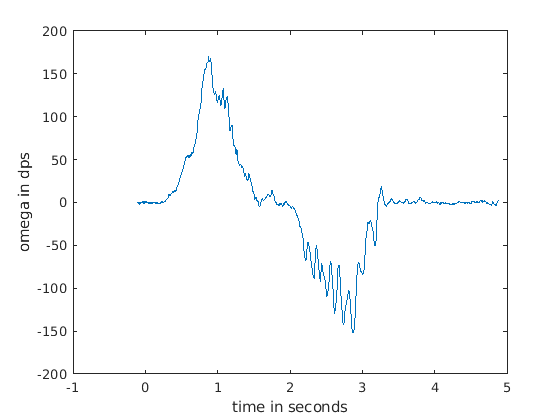

omegadata= step_response_data{:, 3};
figure();
plot(tdata, omegadata);
xlabel("time in seconds");
ylabel("omega in dps"); 

Integrate omega in matlab.

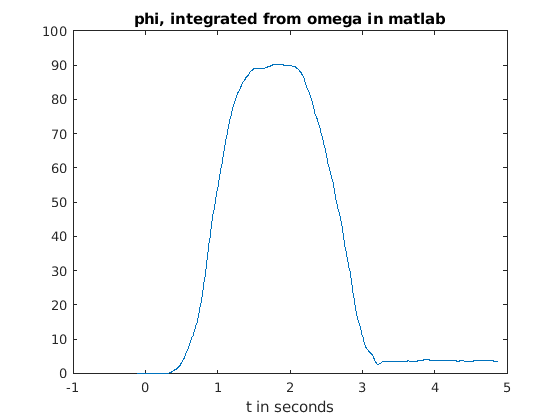

delta_t= 0.005; % seconds
phimatlab= zeros(1, length(tdata)); 
for i=2:length(tdata)
    phimatlab(i)= phimatlab(i-1)+ delta_t* omegadata(i);
end
figure();
plot(tdata, phimatlab); 
title("phi, integrated from omega in matlab");
xlabel("t in seconds");